# Flexible Model of Breast

% Funciona mamaConico3.stl, exportado con 400 triangulos de Fusion360 en
% modo linear para su mesh. En metros. Toma 3 min.
% Usando modo quadratic no se obtuvo resultados, tiempo de simulacion no
% conocido.

% Modelo A: breastA_400.stl - (antes mamaConico4.stl) 400 triangulos
% B: 
% C:
% D:

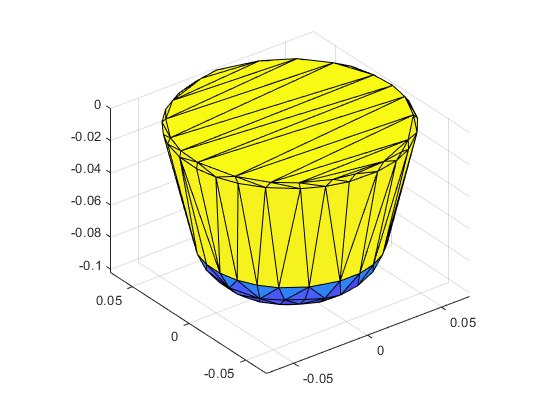

clc, clear
mainPath = startupGUI;
HolderType = 4;
if HolderType==1
    breastPath = strcat(mainPath,'\CAD_models\Breast\breastA_300.stl');
elseif HolderType == 2
    breastPath = strcat(mainPath,'\CAD_models\Breast\breastB_300.stl');
elseif HolderType == 3
    breastPath = strcat(mainPath,'\CAD_models\Breast\breastC_300.stl');
else
    breastPath = strcat(mainPath,'\CAD_models\Breast\breastD_300.stl');
end
%breastPath = strcat(mainPath,'\CAD_models\Breast\mamaConico3.stl');

figure
trisurf(stlread(breastPath))
axis equal

## Step 1: Setting model properties

For breast glandular and fatty tissue Comparaciones ex vs in en Ramiao2016

% In vivo
%Young's modulus in Pa: E 0.1-4k Mira2018
% Eright = 0.3kPa, Eleft = 0.2kPa, Eskin=4kPa Mira2018
% ex vivo:3-60kPa
% in vivo:0.2-6kPa
% superficial layer of superficial fascia: 88.12um
% skin : 2mm
% Eskin_min=7.4 (Han2013); Eskin_max=58.4 (Hendricks2006)
% quasi‐incompressible (Poisson’s ratio = 0.49) for 
%       hyper‐elastic Neo‐Hookean solids

% From lorenzen2002
%breast adipose tissue, breast parenchyma, benign tumor 
%tissue, and malignant tumor tissue were 1.7 kPa, 2.5 kPa, 
%7.0 kPa, and 15.9 kPa, respectively
% From McKignt2002
% G: 3.3 kPa, 7.5 kPa, and 33 kPa: adipose, fibroglandular
% tumor

%From xydeas2005
% lesion sizes 0.5 to 4.5 cm, mean 2.1cm

%From chen2013
%invasive ductal carcinoma is about three times stiffer than
%the adipose tissue and 1.5 times stiffer than the glandular
%tissue.

E_breast = 0.9e3;%En Cheng2013 *** E=0.9 => _Ebreast < E_lesion
% G_breast = 0.34e3% cheng2013: A study of breast motion
rho_breast = 1020;% Mass density kg/m^3 ICR110
nu_breast = 0.495; % Poisson's ratio 0.495 Cheng2013: A study of breast motion

% For skin tissue
% From sinkus for FE: nu=0.48
%From ICR110
% skin: vol=2496.8 cm3; mass=2721.5 g.
% density = mass/vol
% female skin thickness: 1.775 mm
% From Barufaldi2016
% tambien de 1.2 y 1.5
E_skin = 4e3;%Mira2018
rho_skin = 2721.5/2496.8*1000;% about 1.1 g/cm3; 1-1.1 en cheng2013: A study of breast
nu_skin = 0.4;%aprox % 0.495 de cheng2013: A study of breast

% For suspicious mass
E_tar = 1.42e3;%ductal carcinoma Cheng2013
%16.42 invasive ductal carcinoma srivastava2011
%3.5-4 carcinoma sinkus2000
rho_tar = 1170;% about 1.16-1.19 g/cm3 ohno1977
nu_tar = 0.495;%aprox

## Step 2: Specifying locations of interface frames

% Usando la posicion 0 0 -1 mm para el primer interface frame, el modo
% linear funciona, superando la prueba del Calculo de C.
holderHeight = [-57e-3, -59e-3, -67e-3, -70e-3];

origins = [0 0 -1e-3
           0 0 holderHeight(HolderType)]; % Base frame
numFrames = size(origins,1);

## Step 3: Create the Finite-Element Mesh: Breast

feModel = createpde('structural','modal-solid');
importGeometry(feModel,breastPath);
structuralProperties(feModel, ...
    'YoungsModulus',E_breast, ...
    'PoissonsRatio',nu_breast, ...
    'MassDensity',rho_breast);
repMesh = generateMesh(feModel, ...
    'GeometricOrder','quadratic',...
    'Hmax',20e-3, ...
    'Hmin',10e-3);

%Para A
%Hmax 8e-3
%Hmin 1e-3

## Step 4: Set up the Multipoint Constraints for the Interface Frames

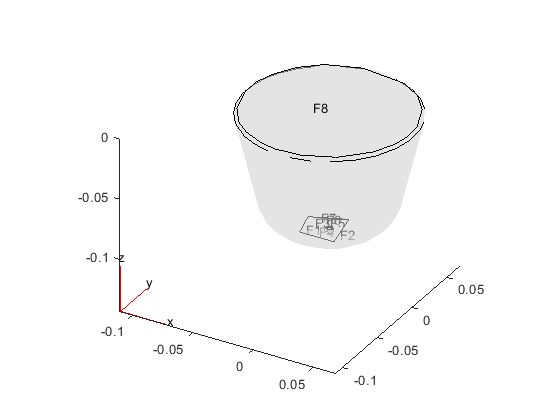

figure
pdegplot(feModel,'FaceLabels','on','FaceAlpha',0.5)

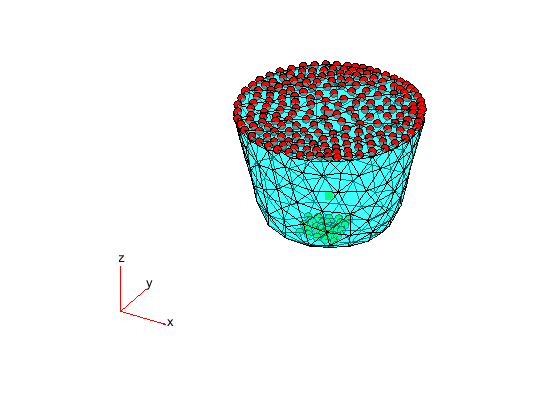

% Selecting desired contraint faces
%IDs = [4,3];% Modelo breastA_400 - 1 -8
%IDs = [4,3]%A300 - 10:15
%IDs = [3,2];%Modelo B_400 - 10:15
%IDs = [6,2];Modelo breastB_300 - 10:15
%IDs = [6,1]%BreastC_300 - 10:15
%IDs = [8 1]%BreastD_300 -
IDs = [8 1];
type = ["Face","Face"];

figure
pdemesh(feModel,'FaceAlpha',0.5)
hold on
colors = ['rgb' repmat('k',1,numFrames-3)];
assert(numel(IDs) == numFrames);
for k = 1:numFrames
    nodeIdxs = findNodes(feModel.Mesh,'region',type(k),IDs(k));
    scatter3( ...
        feModel.Mesh.Nodes(1,nodeIdxs), ...
        feModel.Mesh.Nodes(2,nodeIdxs), ...
        feModel.Mesh.Nodes(3,nodeIdxs), ...
        'ok','MarkerFaceColor',colors(k))
    scatter3( ...
        origins(k,1), ...
        origins(k,2), ...
        origins(k,3), ...
        80,colors(k),'filled','s')
end
hold off


for k = 1:numFrames
    structuralBC(feModel, ...
        type(k),IDs(k), ...
        'Constraint','multipoint', ...
        'Reference',origins(k,:));
end

## Step 5: Generate the Reduced-Order Model

clc
rom = reduce(feModel,'FrequencyRange',[0,1e5]);


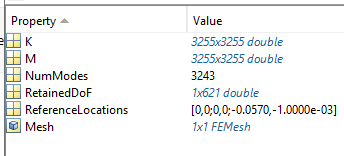

Modelo Excavator

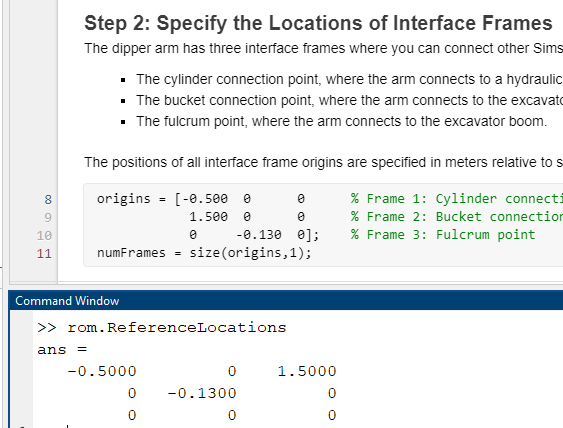

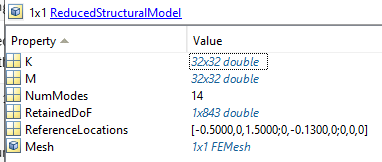

## Computing viscous parameters

breastD.P = rom.ReferenceLocations';  % Interface frame locations (n x 3 matrix)
breastD.K = rom.K;                    % Reduced stiffness matrix
breastD.M = rom.M;                    % Reduced mass matrix

dampingRatio = 0.215;%From cheng2013: A study
breastD.C = computeModalDampingMatrix(dampingRatio,rom.K,rom.M);

%The boundary nodes in the reduced-order model must be specified 
% in the same order as the corresponding interface frames on the block.
% This order is given by the rows of the array origins. If the order of 
% the MPCs is different than the order specified by origins, permute the 
% rows and columns of the various matrices so that they match the original order.
frmPerm = zeros(numFrames,1);    % Frame permutation vector
dofPerm = 1:size(breastD.K,1);    % DOF permutation vector

assert(size(breastD.P,1) == numFrames);
for i = 1:numFrames
    for j = 1:numFrames
        if isequal(breastD.P(j,:),origins(i,:))
            frmPerm(i) = j;
            dofPerm(6*(i-1)+(1:6)) = 6*(j-1)+(1:6);
            continue;
        end
    end
end

assert(numel(frmPerm) == numFrames);
assert(numel(dofPerm) == size(breastD.K,1));

breastD.P = breastD.P(frmPerm,:);
breastD.K = breastD.K(dofPerm,:);
breastD.K = breastD.K(:,dofPerm);
breastD.M = breastD.M(dofPerm,:);
breastD.M = breastD.M(:,dofPerm);
breastD.C = breastD.C(dofPerm,:);
breastD.C = breastD.C(:,dofPerm);

## Step 6: Import Reduced-Order Data

## Uploading to simulation data

% Saving in simulation model data
pathData = strcat(mainPath,"/Simulink_models/Data/simulinkWorkSpace.mat");
save(pathData,'breastD','-append');

## Auxiliar function

function C = computeModalDampingMatrix(dampingRatio,K,M)
% To avoid numerical issues (such as complex eigenvalues with very small
% imaginary parts), make the matrices exactly symmetric.

    K = (K+K')/2;    % Stiffness matrix
    M = (M+M')/2;    % Mass matrix

% Compute the eigen-decomposition associated with the mass and stiffness
% matrices, sorting the eigenvalues in ascending order and permuting
% the corresponding eigenvectors.

    [V,D] = eig(K,M);
    [d,sortIdxs] = sort(diag(D));
    V = V(:,sortIdxs);
% Due to small numerical errors, the six eigenvalues associated with the
% rigid-body modes may not be exactly zero. To avoid numerical issues,
% check that the first six eigenvalues are close enough to zero. Then
% replace them with exact 0 values.

    assert(all(abs(d(1:6))/abs(d(7)) < 1e-9),'Error due to "zero" eigenvalues.');
    d(1:6) = 0;

% Vectors of generalized masses and natural frequencies

    MV = M*V;
    generalizedMasses = diag(V'*MV);
    naturalFrequencies = sqrt(d);

% Compute the modal damping matrix associated with K and M

    C = MV * diag(2*dampingRatio*naturalFrequencies./generalizedMasses) * MV';

end